# Tutorial 3

## Exercise 3.2.1

clear
n = 2:10

n =      2     3     4     5     6     7     8     9    10


fl(1 ./ n)'

ans = 9×1 cell array
    {'+(1.0000000000000000000000000000000000000000000000000000)_2 x 2^(-1)'}
    {'+(1.0101010101010101010101010101010101010101010101010101)_2 x 2^(-2)'}
    {'+(1.0000000000000000000000000000000000000000000000000000)_2 x 2^(-2)'}
    {'+(1.1001100110011001100110011001100110011001100110011010)_2 x 2^(-3)'}
    {'+(1.0101010101010101010101010101010101010101010101010101)_2 x 2^(-3)'}
    {'+(1.0010010010010010010010010010010010010010010010010010)_2 x 2^(-3)'}
    {'+(1.0000000000000000000000000000000000000000000000000000)_2 x 2^(-3)'}
    {'+(1.1100011100011100011100011100011100011100011100011100)_2 x 2^(-4)'}
    {'+(1.1001100110011001100110011001100110011001100110011010)_2 x 2^(-4)'}


## Exercise 3.3

beta = 2; k = 53;
u = 1 / 2 * beta^(1 - k)

u =      1.110223024625157e-16



fl(u)

ans = '+(1.0000000000000000000000000000000000000000000000000000)_2 x 2^(-53)'


L = realmax

L =     1.797693134862316e+308


s = realmin

s =     2.225073858507201e-308



fl(L)

ans = '+(1.1111111111111111111111111111111111111111111111111111)_2 x 2^(1023)'

fl(s)

ans = '+(1.0000000000000000000000000000000000000000000000000000)_2 x 2^(-1022)'


m = -1022;
M = 1023;
s = beta^m

s =     2.225073858507201e-308


## Exercise 3.4.1

L = (beta - beta^(1 - k)) * beta^M

L =     1.797693134862316e+308


1e400

ans =    Inf


realmax * 2

ans =    Inf


1 / inf

ans =      0



0 / 0

ans =    NaN


0 * inf

ans =    NaN


inf - inf

ans =    NaN


 
1 / 0

ans =    Inf


1 / (-0)

ans =   -Inf


## Exercise 3.4.1

clear
0^0

ans =      1


0^inf

ans =      0


inf^0

ans =      1


log(0)

ans =   -Inf


sqrt(-1)

ans =   0.000000000000000 + 1.000000000000000i


## Exercise 3.5

s = realmin
d = realmin / 2^(52)
fl(d)

## Exercise 3.6

fl(prev(0))

ans = '-(0.0000000000000000000000000000000000000000000000000001)_2 x 2^(-1022)'

fl(prev(inf))

ans = '+(1.1111111111111111111111111111111111111111111111111111)_2 x 2^(1023)'

fl(next(realmax))

ans = '+(1.0000000000000000000000000000000000000000000000000000)_2 x 2^(Inf)'

## Exercise 3.7

beta = 2; k = 53;
u = 1 / 2 * beta^(1 - k);
h = u;
e = (1 + h)^(1 / h)

e =      1


fl(1 + h)

ans = '+(1.0000000000000000000000000000000000000000000000000000)_2 x 2^(0)'

h = 2 * u

h =      2.220446049250313e-16


e = (1 + h)^(1 / h)

e =    2.718281828459045


g = @(x) (1 - cos(x)) / x^2

g = function_handle with value:
    @(x)(1-cos(x))/x^2


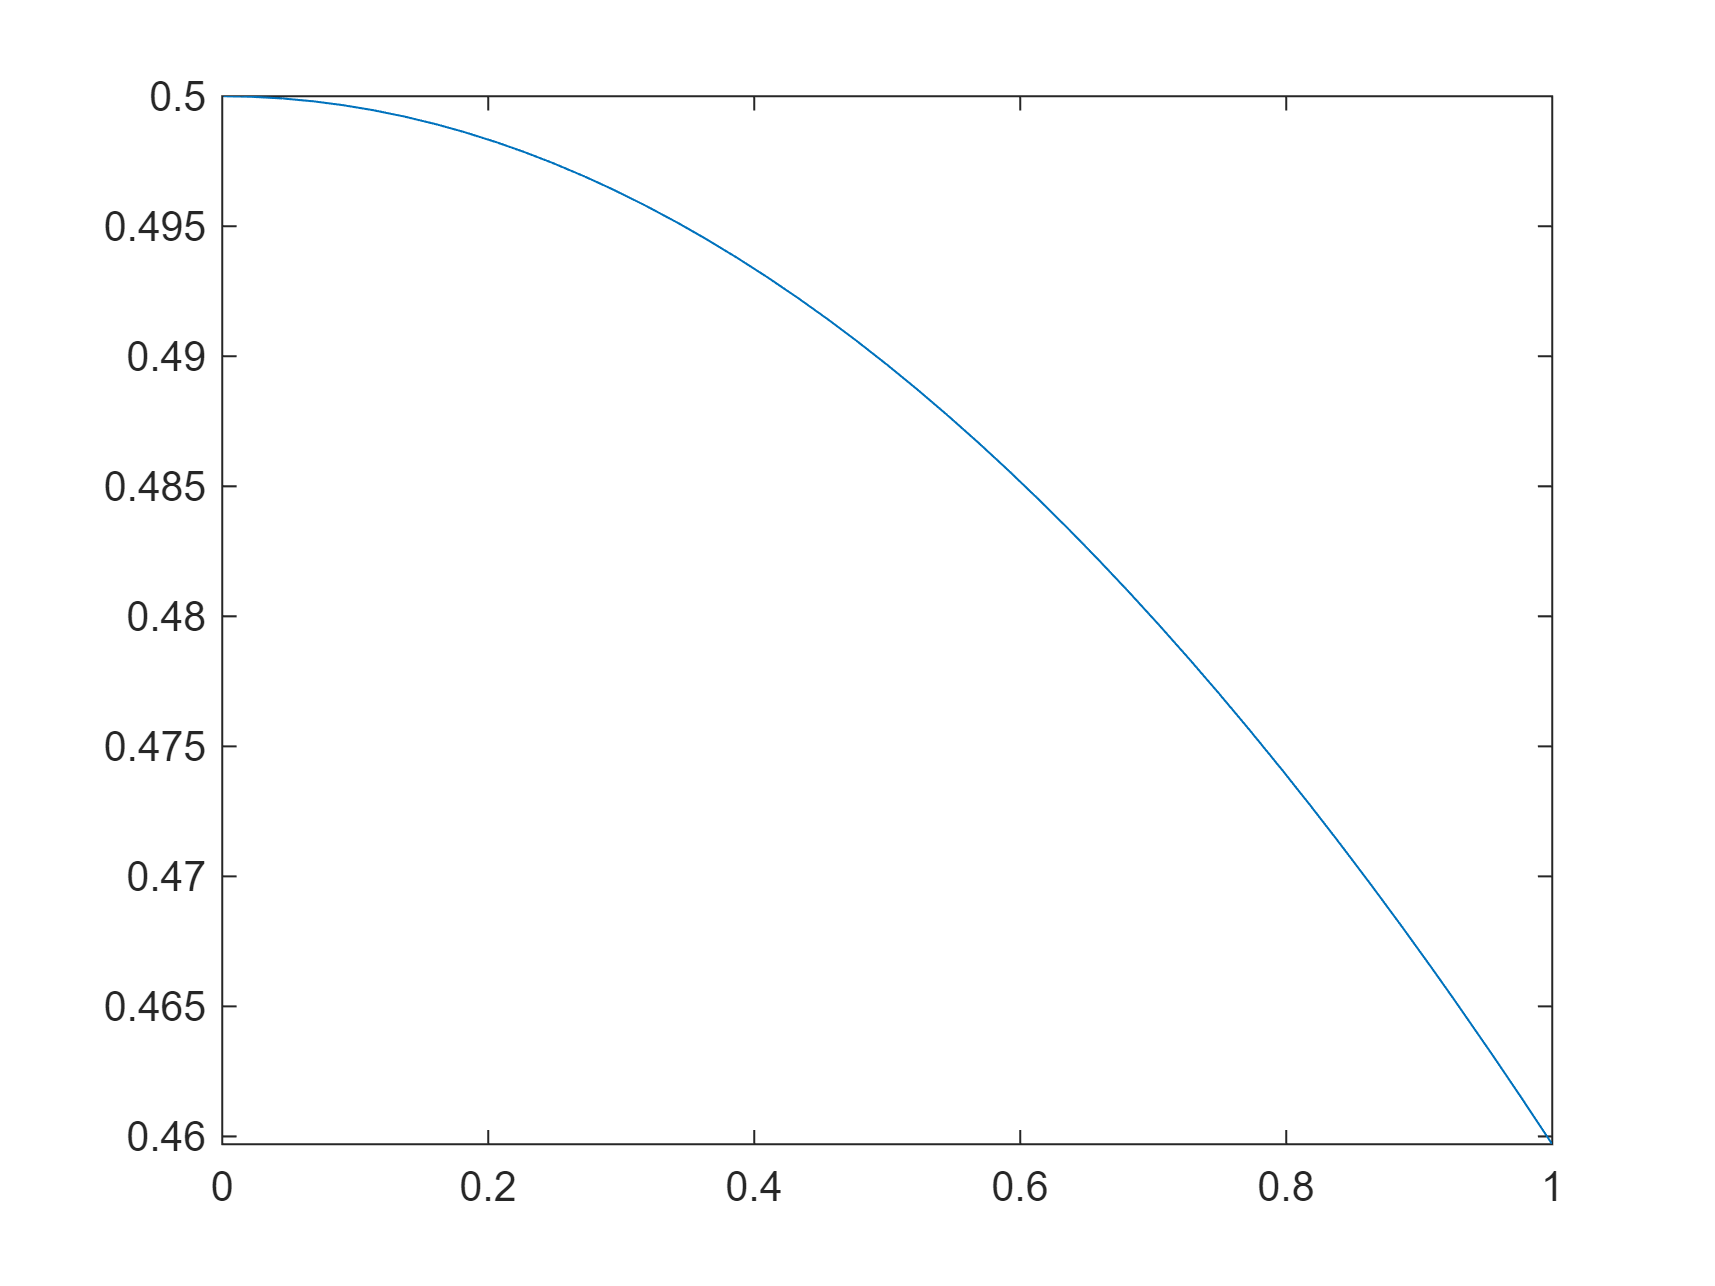

fplot(g, [0, 1])

x = 1.2e-8

x =      1.200000000000000e-08


g(x)

ans =    0.770988211545248
